# Running

👟 Analyze GPX data with Python & MATLAB

GPX (GPS eXchange Format) is an XML based file format for GPS tracks.

### Tomtom

[https://mysports.tomtom.com/](https://mysports.tomtom.com/)

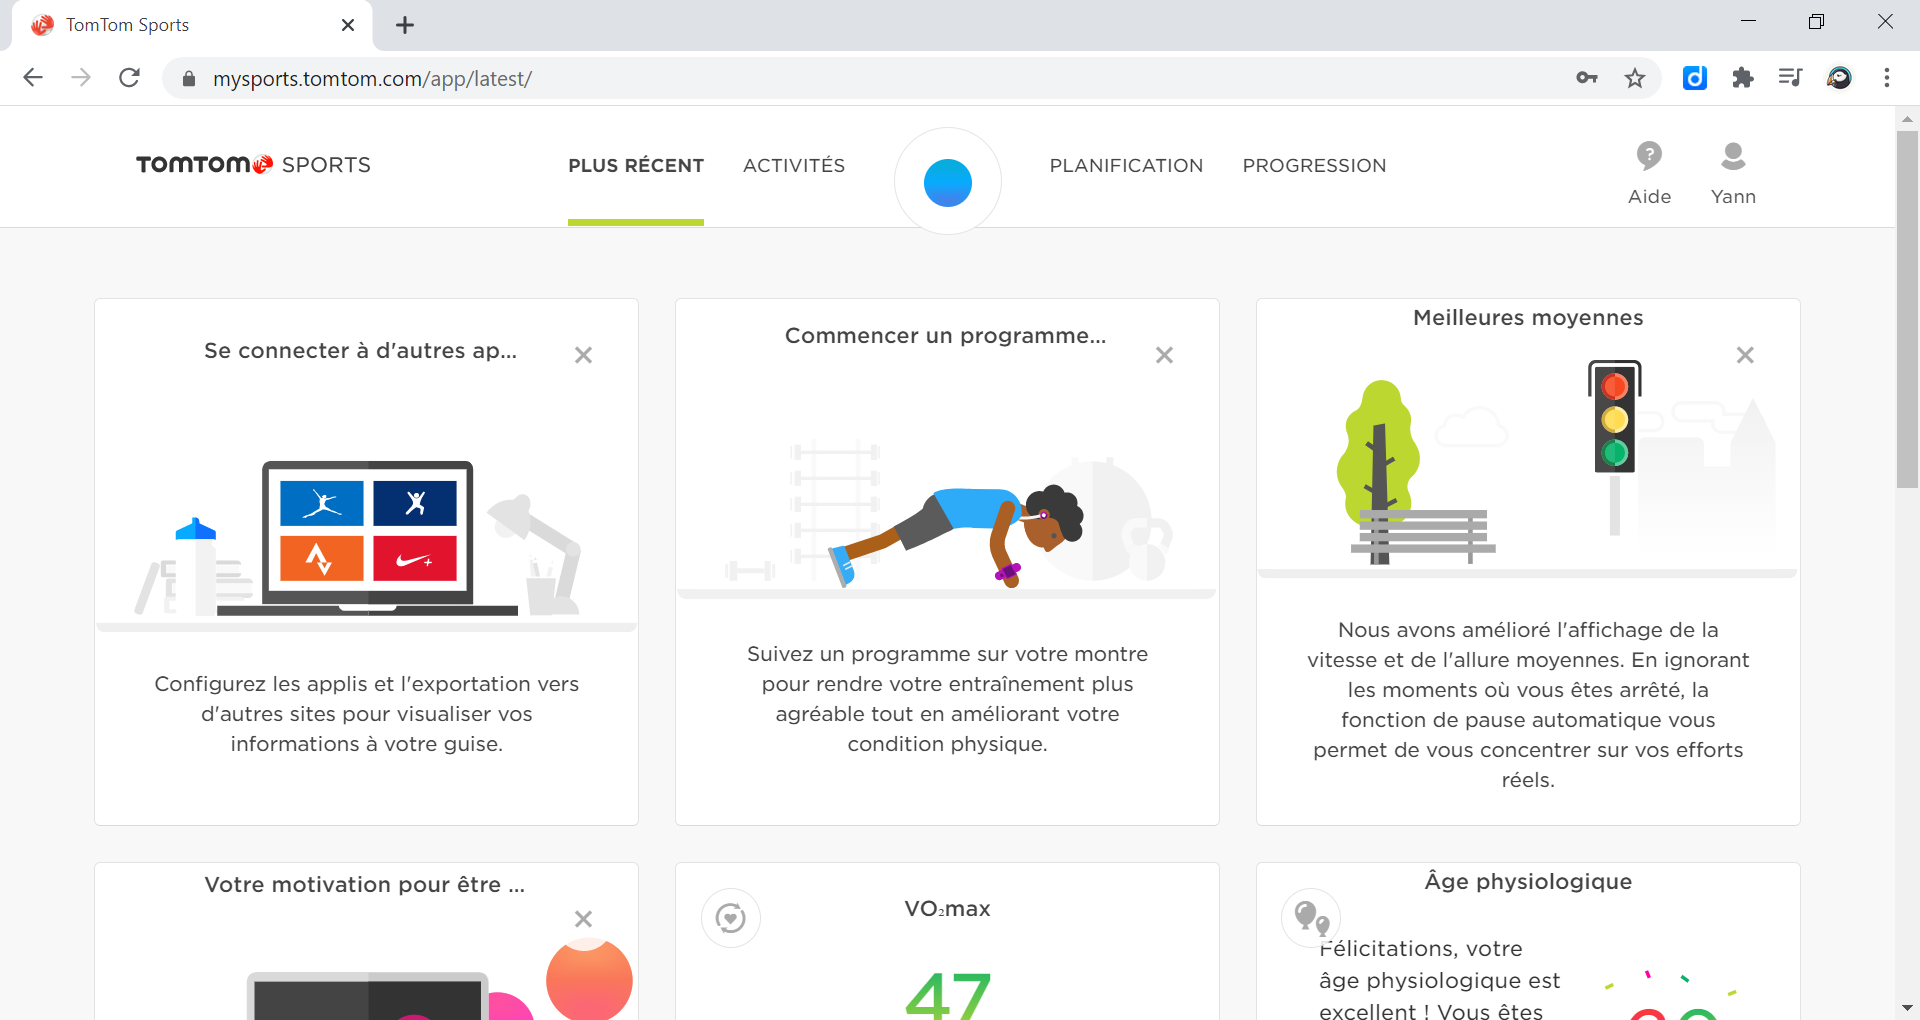

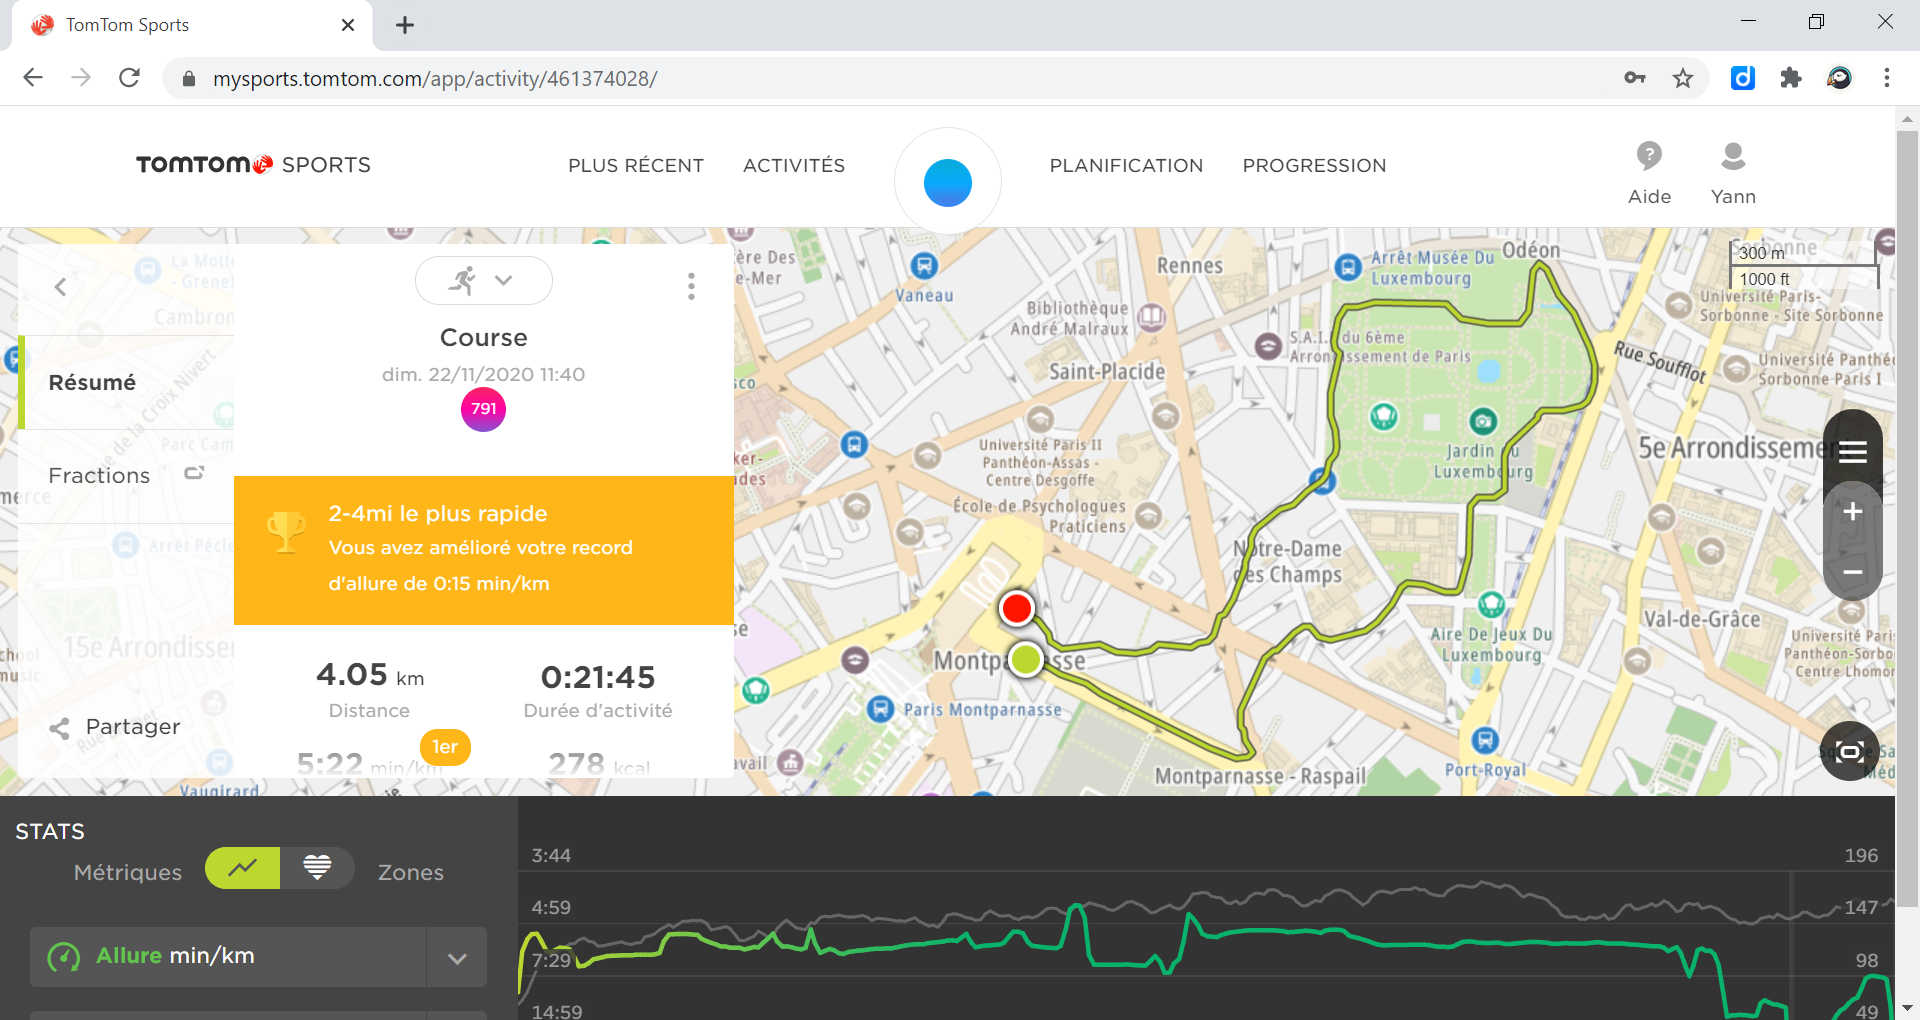

Download as **gpx**

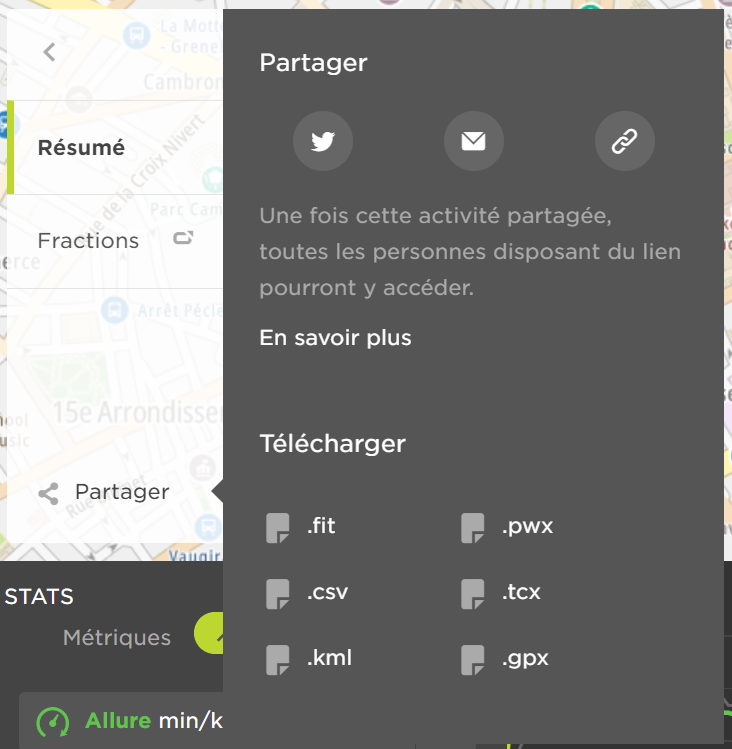

Export all files [https://mysports.tomtom.com/app/settings/exporters/](https://mysports.tomtom.com/app/settings/exporters/)

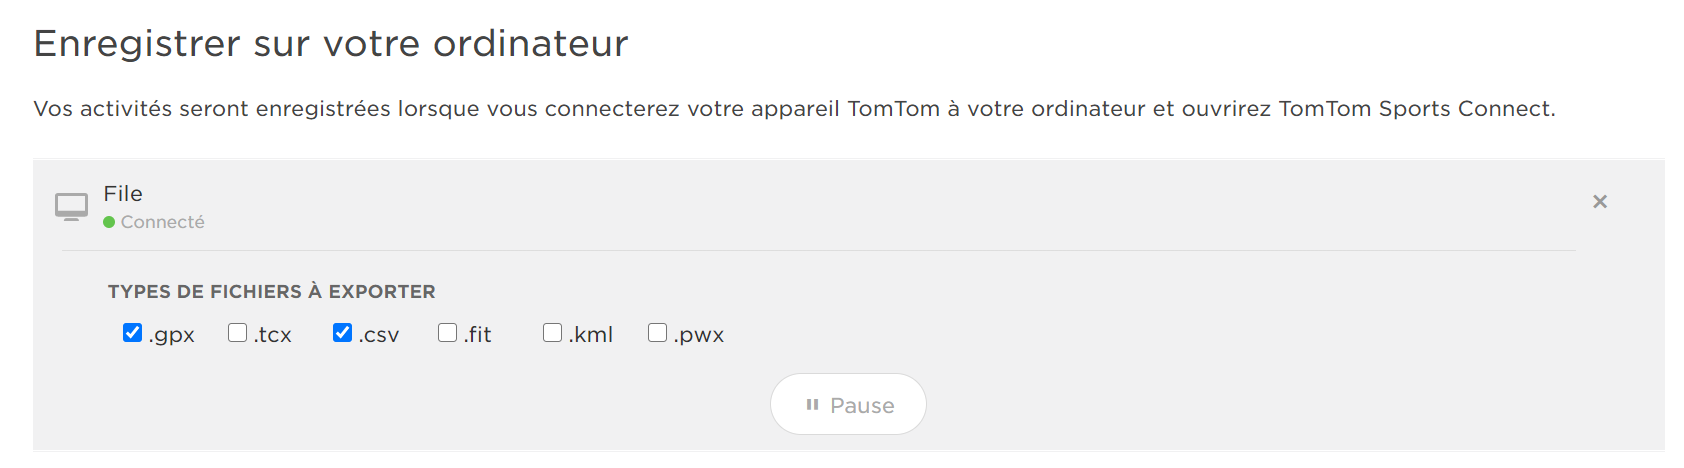

gpx_files = dir("tomtom\*gpx")

gpx_files = 28×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


Open the last file of the list

gpx_file = gpx_files(end)

gpx_file = struct with fields:
       name: 'running_2020-11-11_13-12-41.gpx'
     folder: 'C:\Users\ydebray\Downloads\running\tomtom'
       date: '11-nov.-2020 17:40:51'
      bytes: 392973
      isdir: 0
    datenum: 7.3811e+05


### gpxread

Use [gpxread](https://mathworks.com/help/map/ref/gpxread.html) from the Mapping toolbox

P = gpxread(string(gpx_file.folder)+'\'+string(gpx_file.name))

P =  1070×1 geopoint vector with properties:

 Collection properties:
     Geometry: 'point'
     Metadata: [1×1 struct]
 Feature properties:
     Latitude: [1×1070 double]
    Longitude: [1×1070 double]
    Elevation: [1×1070 double]
         Time: {1×1070 cell}


P.Metadata

ans = struct with fields:
    FeatureType: 'track'
           Name: 'Running'


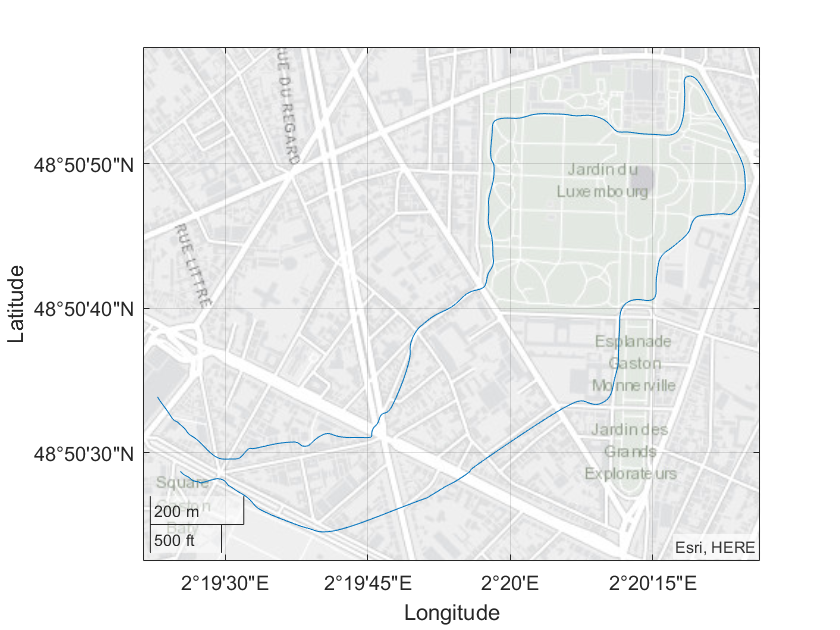

geoplot(P.Latitude,P.Longitude)

P.Time(1)

ans = 1×1 cell array
    {'2020-11-11T12:12:41.000Z'}


datetime(P.Time(1),'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSZ','TimeZone',"Europe/Paris")

ans = datetime
   11-Nov-2020 13:12:41


time = datetime(P.Time,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSZ','TimeZone',"Europe/Paris")

time = 1×1070 datetime array
Columns 1 through 434

   11-Nov-2020 13:12:41   11-Nov-2020 13:12:42   11-Nov-2020 13:12:43   11-Nov-2020 13:12:44   11-Nov-2020 13:12:45   11-Nov-2020 13:12:46   11-Nov-2020 13:12:47   11-Nov-2020 13:12:48   11-Nov-2020 13:12:49   11-Nov-2020 13:12:50   11-Nov-2020 13:12:51   11-Nov-2020 13:12:52   11-Nov-2020 13:12:53   11-Nov-2020 13:12:54   11-Nov-2020 13:12:55   11-Nov-2020 13:12:56   11-Nov-2020 13:12:57   11-Nov-2020 13:12:58   11-Nov-2020 13:12:59   11-Nov-2020 13:13:00   11-Nov-2020 13:13:01   11-Nov-2020 13:13:02   11-Nov-2020 13:13:03   11-Nov-2020 13:13:04   11-Nov-2020 13:13:05   11-Nov-2020 13:13:06   11-Nov-2020 13:13:07   11-Nov-2020 13:13:08   11-Nov-2020 13:13:09   11-Nov-2020 13:13:10   11-Nov-2020 13:13:11   11-Nov-2020 13:13:12   11-Nov-2020 13:13:13   11-Nov-2020 13:13:14   11-Nov-2020 13:13:15   11-Nov-2020 13:13:16   11-Nov-2020 13:13:17   11-Nov-2020 13:13:18   11-Nov-2020 13:13:19   11-Nov-2020 13:13:20   11-Nov-2020 13:13:21   11

T = table(time',P.Latitude',P.Longitude','VariableNames',{'time','lat','lon'})

T = 1070×3 table
            time             lat       lon  
    ____________________    ______    ______

    11-Nov-2020 13:12:41    48.841    2.3237
    11-Nov-2020 13:12:42    48.841    2.3237
    11-Nov-2020 13:12:43    48.841    2.3237
    11-Nov-2020 13:12:44    48.841    2.3237
    11-Nov-2020 13:12:45    48.841    2.3237
    11-Nov-2020 13:12:46    48.841    2.3237
    11-Nov-2020 13:12:47    48.841    2.3237
    11-Nov-2020 13:12:48    48.841    2.3237
    11-Nov-2020 13:12:49    48.841    2.3237
    11-Nov-2020 13:12:50    48.841    2.3237
    11-Nov-2020 13:12:51    48.841    2.3238
    11-Nov-2020 13:12:52    48.841    2.3238
    11-Nov-2020 13:12:53    48.841    2.3238
    11-Nov-2020 13:12:54    48.841    2.3238
    11-Nov-2020 13:12:55    48.841    2.3239
    11-Nov-2020 13:12:56    48.841    2.3239


TT = timetable(time',P.Latitude',P.Longitude','VariableNames',{'lat','lon'})

TT = 1070×2 timetable
            Time             lat       lon  
    ____________________    ______    ______

    11-Nov-2020 13:12:41    48.841    2.3237
    11-Nov-2020 13:12:42    48.841    2.3237
    11-Nov-2020 13:12:43    48.841    2.3237
    11-Nov-2020 13:12:44    48.841    2.3237
    11-Nov-2020 13:12:45    48.841    2.3237
    11-Nov-2020 13:12:46    48.841    2.3237
    11-Nov-2020 13:12:47    48.841    2.3237
    11-Nov-2020 13:12:48    48.841    2.3237
    11-Nov-2020 13:12:49    48.841    2.3237
    11-Nov-2020 13:12:50    48.841    2.3237
    11-Nov-2020 13:12:51    48.841    2.3238
    11-Nov-2020 13:12:52    48.841    2.3238
    11-Nov-2020 13:12:53

### gpxpy

Install [gpxpy](https://pypi.org/project/gpxpy/) GPX file parser from PyPI: 

!pip install gpxpy 

  Using cached https://files.pythonhosted.org/packages/dd/23/a1c04fb3ea8d57d4b46cf2956c99a62dfbe009bbe091babeef90cc3d0ef6/gpxpy-1.4.2.tar.gz 
  Stored in directory: C:\Users\ydebray\AppData\Local\pip\Cache\wheels\d9\df\ed\b52985999b3967fa0ef8de22b3dc8ad3494ce3380d5328dd0f 
Successfully built gpxpy 


cd('tomtom')
py.open(gpx_file.name)

gpx = py.gpxpy.parse(pyfile)

gpx =   Python GPX with properties:

           author_email: [1×1 py.NoneType]
            author_link: [1×1 py.NoneType]
       author_link_text: [1×1 py.NoneType]
       author_link_type: [1×1 py.NoneType]
            author_name: [1×1 py.NoneType]
                 bounds: [1×1 py.NoneType]
       copyright_author: [1×1 py.NoneType]
      copyright_license: [1×1 py.NoneType]
         copyright_year: [1×1 py.NoneType]
                creator: [1×26 py.str]
            description: [1×1 py.NoneType]
             extensions: [1×0 py.list]
               keywords: [1×1 py.NoneType]
                   link: [1×1 py.NoneType]
              link_text: [1×1 py.NoneType]
              link_type: [1×1 py.NoneType]
    metadata_extensions: [1×0 py.list]
                   name: [1×8 py.str]
                  nsmap: [1×1 py.dict]
                 routes: [1×0 py.list]
       schema_locations: [1×2 py.list]
                

track = gpx.tracks(1)

track =   Python list with no properties.

    [GPXTrack(name='Running', segments=[GPXTrackSegment(points=[...])])]


Seg = track(1)

Seg =   Python list with no properties.

    [GPXTrack(name='Running', segments=[GPXTrackSegment(points=[...])])]


### Python User-Defined Function

coord = py.running.parse('tomtom/'+string(gpx_file.name))

coord =   Python list with no properties.

    [[48.841315, 48.841316, 48.841315, 48.841313, 48.84131, 48.841305, 48.8413, 48.841293, 48.841286, 48.841278, 48.841268, 48.841258, 48.841248, 48.841236, 48.841224, 48.841211, 48.841198, 48.841183, 48.841168, 48.841152, 48.841139, 48.841127, 48.841119, 48.841113, 48.841099, 48.84109, 48.841145, 48.841174, 48.841173, 48.84117, 48.841166, 48.841161, 48.841153, 48.841143, 48.84113, 48.841115, 48.841098, 48.841081, 48.841065, 48.841053, 48.841043, 48.841037, 48.841031, 48.841024, 48.841015, 48.841005, 48.840992, 48.840978, 48.840963, 48.840948, 48.840931, 48.840915, 48.840898, 48.840881, 48.840863, 48.840843, 48.840822, 48.840798, 48.840773, 48.840745, 48.840716, 48.840686, 48.840657, 48.840632, 48.84061, 48.840593, 48.840578, 48.840564, 48.840551, 48.840538, 48.840526, 48.840514, 48.840502, 48.84049, 48.840478, 48.840467, 48.840455, 48.840444, 48.840433, 48.840421, 48.84041, 48.84

c = cell(coord)

c = 1×2 cell array
    {1×1070 py.list}    {1×1070 py.list}


c(1)

ans = 1×1 cell array
    {1×1070 py.list}


coord2 = py.running.parse2('tomtom/'+string(gpx_file.name))

coord2 =   Python dict with no properties.

    {'lat': [48.841315, 48.841316, 48.841315, 48.841313, 48.84131, 48.841305, 48.8413, 48.841293, 48.841286, 48.841278, 48.841268, 48.841258, 48.841248, 48.841236, 48.841224, 48.841211, 48.841198, 48.841183, 48.841168, 48.841152, 48.841139, 48.841127, 48.841119, 48.841113, 48.841099, 48.84109, 48.841145, 48.841174, 48.841173, 48.84117, 48.841166, 48.841161, 48.841153, 48.841143, 48.84113, 48.841115, 48.841098, 48.841081, 48.841065, 48.841053, 48.841043, 48.841037, 48.841031, 48.841024, 48.841015, 48.841005, 48.840992, 48.840978, 48.840963, 48.840948, 48.840931, 48.840915, 48.840898, 48.840881, 48.840863, 48.840843, 48.840822, 48.840798, 48.840773, 48.840745, 48.840716, 48.840686, 48.840657, 48.840632, 48.84061, 48.840593, 48.840578, 48.840564, 48.840551, 48.840538, 48.840526, 48.840514, 48.840502, 48.84049, 48.840478, 48.840467, 48.840455, 48.840444, 48.840433, 48.840421, 48.8404

c2 = struct(coord2)

c2 = struct with fields:
    lat: [1×1070 py.list]
    lon: [1×1070 py.list]


lat = cell(c2.lat)

lat = 1×1070 cell array
  Columns 1 through 666

    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8413]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8412]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8411]}    {[48.8410]}    {[48.8410]}    {[48.8410]}    {[48.8410]}    {[48.8410]}    {[48.8410]}    {[48.8410]}    {[48.8410]}    {[48.8410]}    {[48.8409]}    {[48.8409]}    {[48.8409]}    {[48.8409]}    {[48.8409]}    {[48.8409]}    {[48.8408]}    {[48.8408]}    {[48.8408]}    {[48.8408]}    {[48.8407]}    {[48.8407]}    {[48.8407]}    {[48.8407]}    {[

lon = cell(c2.lon)

lon = 1×1070 cell array
  Columns 1 through 714

    {[2.3237]}    {[2.3237]}    {[2.3237]}    {[2.3237]}    {[2.3237]}    {[2.3237]}    {[2.3237]}    {[2.3237]}    {[2.3237]}    {[2.3237]}    {[2.3238]}    {[2.3238]}    {[2.3238]}    {[2.3238]}    {[2.3239]}    {[2.3239]}    {[2.3239]}    {[2.3240]}    {[2.3240]}    {[2.3240]}    {[2.3240]}    {[2.3241]}    {[2.3241]}    {[2.3242]}    {[2.3243]}    {[2.3243]}    {[2.3246]}    {[2.3247]}    {[2.3248]}    {[2.3248]}    {[2.3248]}    {[2.3249]}    {[2.3249]}    {[2.3249]}    {[2.3250]}    {[2.3250]}    {[2.3250]}    {[2.3250]}    {[2.3251]}    {[2.3251]}    {[2.3251]}    {[2.3251]}    {[2.3251]}    {[2.3251]}    {[2.3252]}    {[2.3252]}    {[2.3252]}    {[2.3252]}    {[2.3253]}    {[2.3253]}    {[2.3254]}    {[2.3254]}    {[2.3254]}    {[2.3255]}    {[2.3255]}    {[2.3256]}    {[2.3256]}    {[2.3257]}    {[2.3257]}    {[2.3257]}    {[2.3258]}    {[2.3258]}    {[2.3259]}    {[2.3259]}    {[2.3259]}    {[2.3260]}    {[2.3260]}    {[2.3261]

### Runtastic

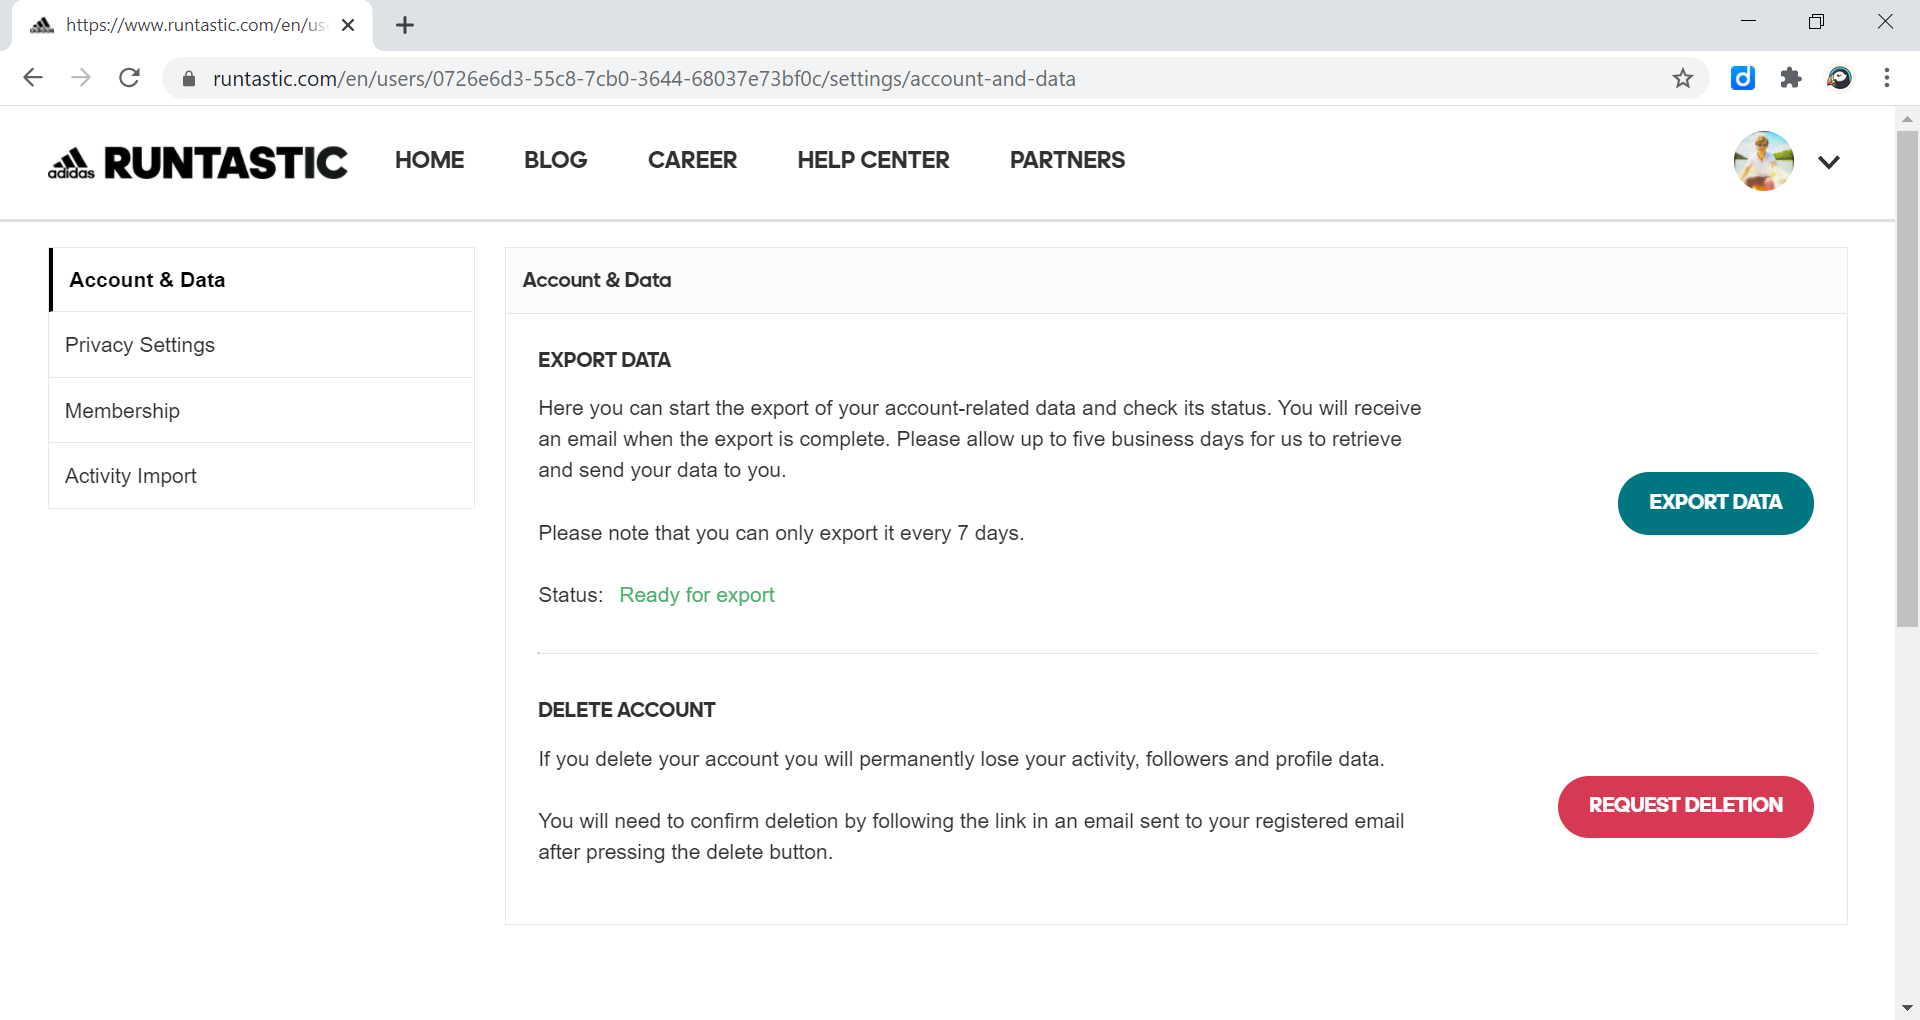

### Reload

Reload `running.py` after modifications

clear classes
mod = py.importlib.import_module('running'); 
py.importlib.reload(mod); 